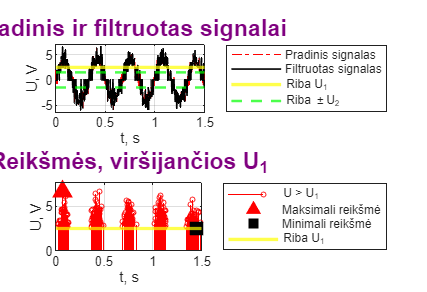

clear
close all

t = 0:0.002:1.5;
A = 4;
f = 3;
sigma = 1;
U1 = 2.5;
U2 = 1.5;

s = A*sin(2*pi*f*t);
n = sigma*randn(size(t));
x = s + n;

xf = x;
xf(abs(xf) < U2) = 0;

iv = x > U1;
tv = t(iv);
xv = x(iv);
imax = xv == max(xv);
imin = xv == min(xv);

violetine = [0.5 0 0.5];

fig = figure('Position', [100 100 1100 750], 'Color', 'w');
try
    theme(fig, 'light');
end

subplot(2,1,1);
plot(t, x, 'r-.');
hold on;
plot(t, xf, 'k-', 'LineWidth', 1);
yline(U1, 'y', 'LineWidth', 2);
yline(U2, 'g--', 'LineWidth', 1.5);
yline(-U2, 'g--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
hold off;
grid on;
xlim([0 1.5]);
ylim([min(x)-0.5, max(x)+0.5]);
title('Pradinis ir filtruotas signalai', 'Color', violetine, 'FontSize', 14);
xlabel('t, s');
ylabel('U, V');
legend('Pradinis signalas', 'Filtruotas signalas', 'Riba U_1', 'Riba \pmU_2', 'Location', 'eastoutside');

subplot(2,1,2);
stem(tv, xv, 'r', 'MarkerSize', 3);
hold on;
plot(tv(imax), xv(imax), 'r^', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(tv(imin), xv(imin), 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
yline(U1, 'y', 'LineWidth', 2);
hold off;
grid on;
xlim([0 1.5]);
ylim([0, max(xv)+1]);
title('Reikšmės, viršijančios U_1', 'Color', violetine, 'FontSize', 14);
xlabel('t, s');
ylabel('U, V');
legend('U > U_1', 'Maksimali reikšmė', 'Minimali reikšmė', 'Riba U_1', 'Location', 'eastoutside');